proportoion_test1

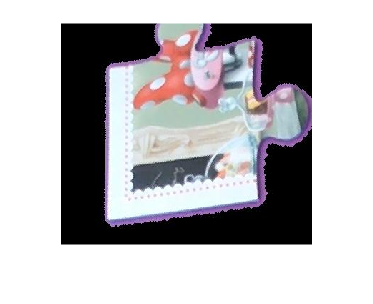

RGB=imread('../image_pices_test\p_7.jpg');
imshow(RGB)

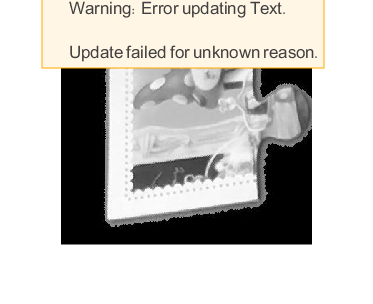


I=double(rgb2gray(RGB))/255;
imshow(I)

%  ginput(4)
% x=[   65.3843338213762
% 270.328696925329
% 277.114934114202
% 67.1939970717423];
% y=[57.7306002928258
% 21.0849194729137
% 245.935578330893
% 274.890190336750];
x=[65.0000000000000
65.0000000000000
347.000000000000
353.000000000000];
y=[1
276
240.000000000000
6]

y =      1
   276
   240
     6


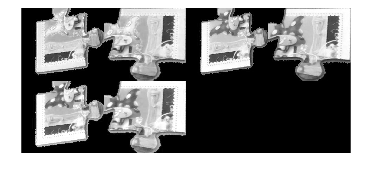


[N,M]=size(I);
fixedPoints = [0 0; M 0; M N; 0 N];
tform = fitgeotrans([x(1) y(1); x(2) y(2); x(3) y(3); x(4) y(4)],fixedPoints,'projective');
I2 = imwarp(RGB,tform,'OutputView',imref2d(size(I)));
figure
montage([RGB,I2])

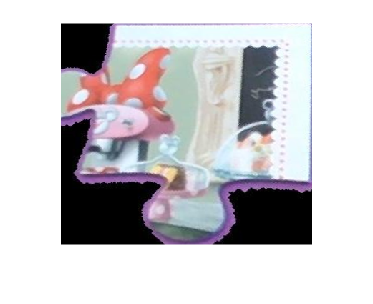

imshow(I2)

% imwrite(I2 ,'../image_pices_test\p_7_1.jpg')
